%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%  auther:
%  Key Laboratory of Intelligent Perception and Image Understanding of Ministry
%  of Education, International Research Center for Intelligent Perception and
%  Computation, Xidian University, Xian 710071,China(e-mail:zelianwen@foxmail.com).
%  version:PSO-SIFT-matlab-V1.0
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

close all;
clear all;

## image path

file_image='F:\class_file\图像配准\图像配准';

## read two images

[filename,pathname]=uigetfile({'*.*','All Files(*.*)'},'Select reference image',...
    file_image);
image_1=imread(strcat(pathname,filename));
[filename,pathname]=uigetfile({'*.*','All Files(*.*)'},'Select the image to be registered',...
    file_image);
image_2=imread(strcat(pathname,filename));

## Display the reference image and the image to be registered

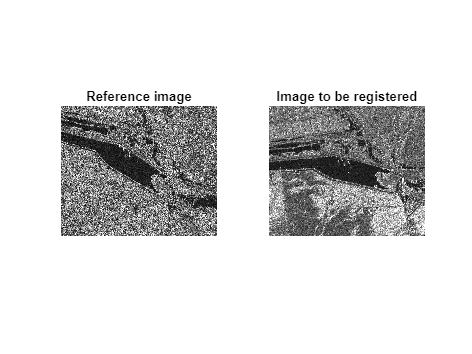

figure;
subplot(1,2,1);
imshow(image_1);
title('Reference image');
subplot(1,2,2);
imshow(image_2);
title('Image to be registered');

## make file for save images

if (exist('save_image','dir')==0)%如果文件夹不存在
    mkdir('save_image');
end

t1=clock;%Start time

## Convert input image format

[~,~,num1]=size(image_1);
[~,~,num2]=size(image_2);
if(num1==3)
    image_11=rgb2gray(image_1);
else
    image_11=image_1;
end
if(num2==3)
    image_22=rgb2gray(image_2);
else
    image_22=image_2;
end

%Converted to floating point data between 0-1
image_11=im2double(image_11);
image_22=im2double(image_22);

## Define the constants used

sigma=1.6;%Bottom Gauss Pyramid scale
dog_center_layer=3;%Defines the DOG Pyramid intermediate layer, the default is 3
contrast_threshold_1=0.04;%Contrast threshold of reference image
contrast_threshold_2=0.04;%Contrast threshold of the image to be registered
edge_threshold=10;%Edge threshold
is_double_size=false;%Whether the image size is enlarged,the default is 'false',to get more points, set it to 'true'
change_form='similarity';%Select geometric transformation type,it can be 'similarity','affine'

## The number of groups in Gauss Pyramid

nOctaves_1=num_octaves(image_11,is_double_size);
nOctaves_2=num_octaves(image_22,is_double_size);

## Generation of the first layer of the Gauss scale image

image_11=create_initial_image(image_11,is_double_size,sigma);
image_22=create_initial_image(image_22,is_double_size,sigma);

## Generating Gauss Pyramid of reference image

tic;
[gaussian_pyramid_1,gaussian_gradient_1,gaussian_angle_1]=...
    build_gaussian_pyramid(image_11,nOctaves_1,dog_center_layer,sigma);
disp(['Reference image generation Gauss Pyramid spent time is：',num2str(toc),'s']);

Reference image generation Gauss Pyramid spent time is：0.17033s


## Generating DOG Pyramid of reference image

tic;
dog_pyramid_1=build_dog_pyramid(gaussian_pyramid_1,nOctaves_1,dog_center_layer);
disp(['Reference image generation DOG Pyramid spent time is：',num2str(toc),'s']);

Reference image generation DOG Pyramid spent time is：0.015243s


clear gaussian_pyramid_1;

## Search for extreme points in the DOG Pyramid of the reference image

tic;
[key_point_array_1]=find_scale_space_extream...
    (...
    dog_pyramid_1,...
    nOctaves_1,...
    dog_center_layer,...
    contrast_threshold_1,...
    sigma,...
    edge_threshold,...
    gaussian_gradient_1,...
    gaussian_angle_1...
    );
disp(['The extreme points of the reference image detection spend time is：',num2str(toc),'s']);

The extreme points of the reference image detection spend time is：0.24599s


clear dog_pyramid_1;

## The feature point descriptor generation,Reference image

tic;
[descriptors_1,locs_1]=calc_descriptors(gaussian_gradient_1,gaussian_angle_1,.....
    key_point_array_1,is_double_size);
disp(['Reference image feature point descriptor generation spend time is：',num2str(toc),'s']);

Reference image feature point descriptor generation spend time is：0.48583s


clear gaussian_gradient_1;
clear gaussian_angle_1;

## Generating Gauss Pyramid of the image to be registered

tic;
[gaussian_pyramid_2,gaussian_gradient_2,gaussian_angle_2]=...
    build_gaussian_pyramid(image_22,nOctaves_2,dog_center_layer,sigma);
disp(['The image to be registered generation Gauss Pyramid spent time is：',num2str(toc),'s']);

The image to be registered generation Gauss Pyramid spent time is：0.11074s


## Generating DOG Pyramid of the image to be registered

tic;
dog_pyramid_2=build_dog_pyramid(gaussian_pyramid_2,nOctaves_2,dog_center_layer);
disp(['The image to be registered generation DOG Pyramid spent time is：：',num2str(toc),'s']);

The image to be registered generation DOG Pyramid spent time is：：0.015424s


clear gaussian_pyramid_2;

## Search for extreme points int the DOG Pyramid of the image to be registered

tic;
[key_point_array_2]=find_scale_space_extream...
    (...
    dog_pyramid_2,...
    nOctaves_2,...
    dog_center_layer,...
    contrast_threshold_2,...
    sigma,...
    edge_threshold,...
    gaussian_gradient_2,...
    gaussian_angle_2...
    );
disp(['The extreme points of the image to be registered detection spend time is：',num2str(toc),'s']);

The extreme points of the image to be registered detection spend time is：0.18686s


clear dog_pyramid_2;

## The feature point descriptor generation,the image to be registered

tic;
[descriptors_2,locs_2]=calc_descriptors(gaussian_gradient_2,gaussian_angle_2,...
    key_point_array_2,is_double_size);
disp(['The image to be registered feature point descriptor generation spend time is：',num2str(toc),'s']);

The image to be registered feature point descriptor generation spend time is：0.64693s


clear gaussian_gradient_2;
clear gaussian_angle_2;

## Calculation of geometric transformation parameters

NNDR Found 148 matches.


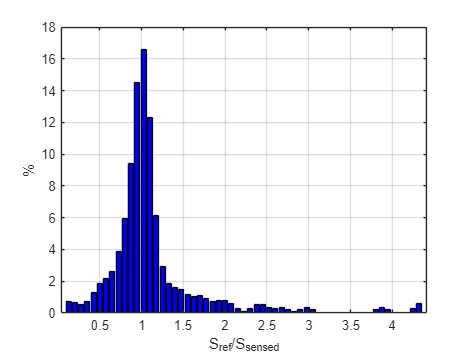

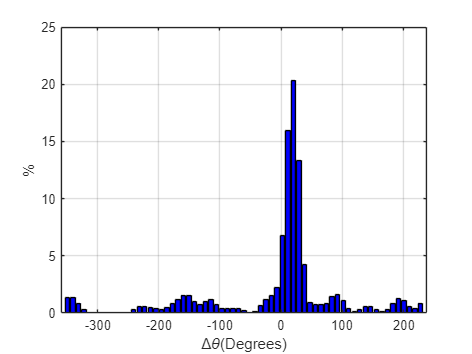

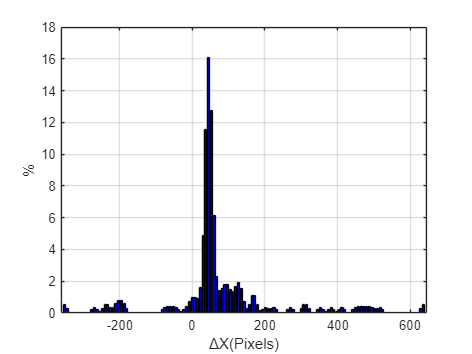

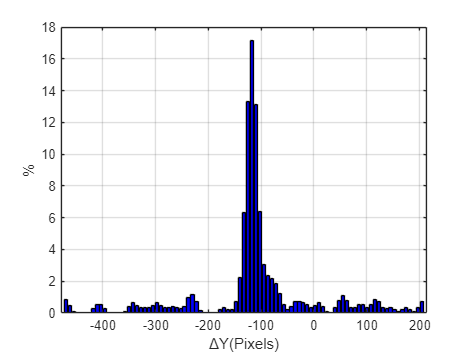

Initial matching points is：13 matches.


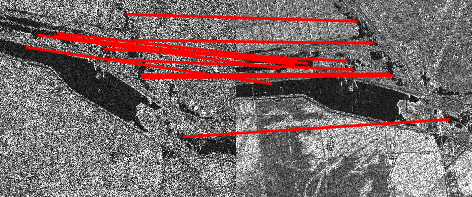

Finally, the number of correct matching points is：23 matches.


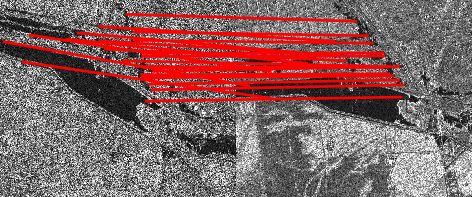

tic;
[solution,~,cor1,cor2]=...
    match(image_2, image_1,descriptors_2,locs_2,descriptors_1,locs_1,change_form);

disp(['Feature point matching spend time is：',num2str(toc),'s']);

Feature point matching spend time is：10.4324s


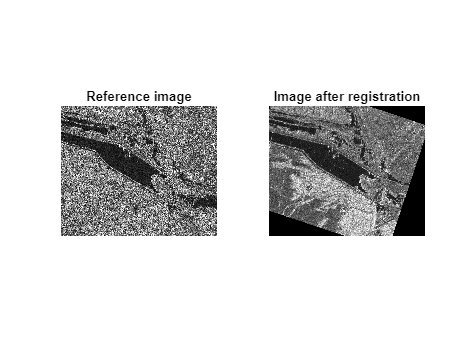


tform=maketform('projective',solution');
[M,N,P]=size(image_1);
ff=imtransform(image_2,tform, 'XData',[1 N], 'YData',[1 M]);
button=figure;
subplot(1,2,1);
imshow(image_1);
title('Reference image');
subplot(1,2,2);
imshow(ff);
title('Image after registration');
str1=['.\save_image\','Results after registration','.jpg'];
saveas(button,str1,'jpg');

t2=clock;
disp(['Total spending time is：',num2str(etime(t2,t1)),'s']);

Total spending time is：13.351s


## Display the detected feature points on the image

[button1,button2]=showpoint_detected(image_1,image_2,locs_1,locs_2);

The number of feature points for reference image detection is 1529.
The number of feature points for image detection to be registered is 1996.


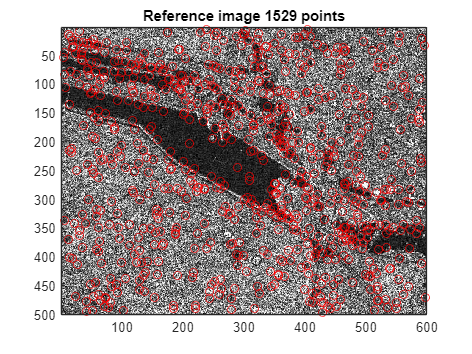

str1=['.\save_image\','Reference image detection point','.jpg'];
saveas(button1,str1,'jpg');

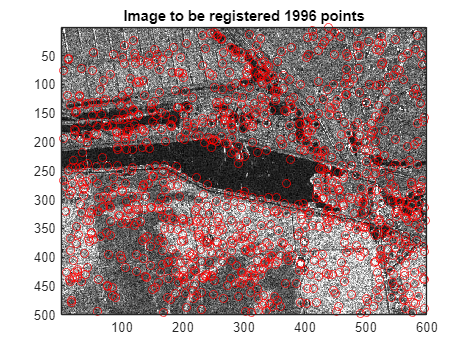

str1=['.\save_image\','Points detected in the image to be registered','.jpg'];
saveas(button2,str1,'jpg');

## Image fusion

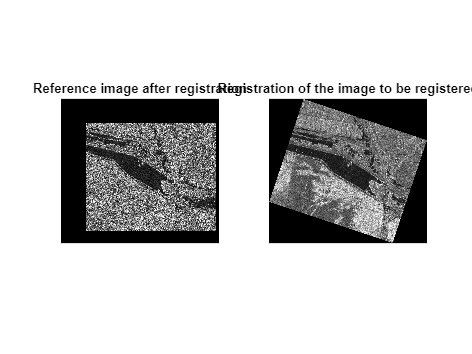

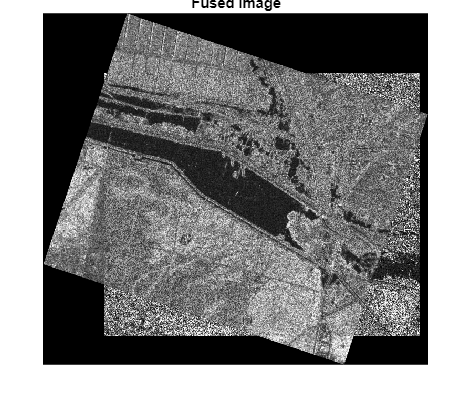

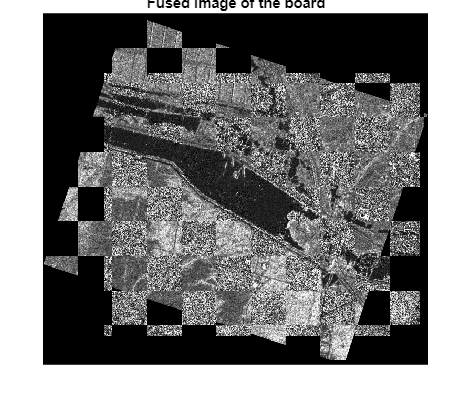

image_fusion(image_1,image_2,solution);